clear;

% training data
numBoundaryConditionPoints = [25 25];

x0BC1 = -1*ones(1,numBoundaryConditionPoints(1));
x0BC2 = ones(1,numBoundaryConditionPoints(2));

t0BC1 = linspace(0,1,numBoundaryConditionPoints(1));
t0BC2 = linspace(0,1,numBoundaryConditionPoints(2));

u0BC1 = zeros(1,numBoundaryConditionPoints(1));
u0BC2 = zeros(1,numBoundaryConditionPoints(2));

numInitialConditionPoints  = 50;

x0IC = linspace(-1,1,numInitialConditionPoints);
t0IC = zeros(1,numInitialConditionPoints);
u0IC = -sin(pi*x0IC);

X0 = [x0IC x0BC1 x0BC2];
T0 = [t0IC t0BC1 t0BC2];
U0 = [u0IC u0BC1 u0BC2];

numInternalCollocationPoints = 10^4;

points = rand(numInternalCollocationPoints,2);

dataX = 2*points(:,1)-1;
dataT = points(:,2);

% define neural network
numBlocks = 8;
fcOutputSize = 20;

fcBlock = [
    fullyConnectedLayer(fcOutputSize)
    tanhLayer];

layers = [
    featureInputLayer(2)
    repmat(fcBlock,[numBlocks 1])
    fullyConnectedLayer(1)]

net = dlnetwork(layers)

net = dlupdate(@double,net);

% training opts
solverState = lbfgsState;
maxIterations = 1500;
gradientTolerance = 1e-5;
stepTolerance = 1e-5;

% train it!!!
X = dlarray(dataX,"BC");
T = dlarray(dataT,"BC");
X0 = dlarray(X0,"CB");
T0 = dlarray(T0,"CB");
U0 = dlarray(U0,"CB");

accfun = dlaccelerate(@modelLoss);

lossFcn = @(net) dlfeval(accfun,net,X,T,X0,T0,U0);

monitor = trainingProgressMonitor( ...
    Metrics="TrainingLoss", ...
    Info=["Iteration" "GradientsNorm" "StepNorm"], ...
    XLabel="Iteration");

iteration = 0;
while iteration < maxIterations && ~monitor.Stop
    iteration = iteration + 1;
    [net, solverState] = lbfgsupdate(net,lossFcn,solverState);

    updateInfo(monitor, ...
        Iteration=iteration, ...
        GradientsNorm=solverState.GradientsNorm, ...
        StepNorm=solverState.StepNorm);

    recordMetrics(monitor,iteration,TrainingLoss=solverState.Loss);

    monitor.Progress = 100*iteration/maxIterations;

    if solverState.GradientsNorm < gradientTolerance || ...
            solverState.StepNorm < stepTolerance || ...
            solverState.LineSearchStatus == "failed"
        break
    end

end

% evaluate accuracy
tTest = [0.25 0.50 0.75 1.00];
numObservationsTest = numel(tTest);

szXTest = 1001;
XTest = linspace(-1,1,szXTest);
XTest = dlarray(XTest,"CB");

UPred = zeros(numObservationsTest,szXTest);
UTest = zeros(numObservationsTest,szXTest);

for i = 1:numObservationsTest
    t = tTest(i);

    TTest = repmat(t,[1 szXTest]);
    TTest = dlarray(TTest,"CB");
    XTTest = cat(1,XTest,TTest);

    UPred(i,:) = forward(net,XTTest);
    UTest(i,:) = solveBurgers(extractdata(XTest),t,0.01/pi);
end

err = norm(UPred - UTest) / norm(UTest)

err = 0.0173

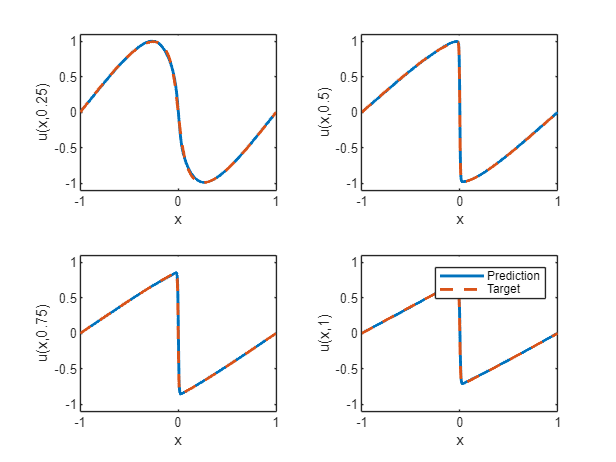


figure
tiledlayout("flow")

for i = 1:numel(tTest)
    nexttile
    
    plot(XTest,UPred(i,:),"-",LineWidth=2);

    hold on
    plot(XTest, UTest(i,:),"--",LineWidth=2)
    hold off

    ylim([-1.1, 1.1])
    xlabel("x")
    ylabel("u(x," + tTest(i) + ")")
end

legend(["Prediction" "Target"])

% define loss function
function [loss,gradients] = modelLoss(net,X,T,X0,T0,U0)

% Make predictions with the initial conditions.
XT = cat(1,X,T);
U = forward(net,XT);

% Calculate derivatives with respect to X and T.
X = stripdims(X);
T = stripdims(T);
U = stripdims(U);
Ux = dljacobian(U,X,1);
Ut = dljacobian(U,T,1);

% Calculate second-order derivatives with respect to X.
Uxx = dldivergence(Ux,X,1);

% Calculate mseF. Enforce Burger's equation.
f = Ut + U.*Ux - (0.01./pi).*Uxx;
mseF = mean(f.^2);

% Calculate mseU. Enforce initial and boundary conditions.
XT0 = cat(1,X0,T0);
U0Pred = forward(net,XT0);
mseU = l2loss(U0Pred,U0);

% Calculated loss to be minimized by combining errors.
loss = mseF + mseU;

% Calculate gradients with respect to the learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

% burgers
function U = solveBurgers(X,t,nu)

% Define functions.
f = @(y) exp(-cos(pi*y)/(2*pi*nu));
g = @(y) exp(-(y.^2)/(4*nu*t));

% Initialize solutions.
U = zeros(size(X));

% Loop over x values.
for i = 1:numel(X)
    x = X(i);

    % Calculate the solutions using the integral function. The boundary
    % conditions in x = -1 and x = 1 are known, so leave 0 as they are
    % given by initialization of U.
    if abs(x) ~= 1
        fun = @(eta) sin(pi*(x-eta)) .* f(x-eta) .* g(eta);
        uxt = -integral(fun,-inf,inf);
        fun = @(eta) f(x-eta) .* g(eta);
        U(i) = uxt / integral(fun,-inf,inf);
    end
end

end